% Initialization taken from "neural_network_quantization.mlx"

[rng_seed, N_data_points, data_dimension, layer_0_dimension, output_dimension] = hyperparameters(0);
rng(rng_seed)

[input_data, calibration_data, layer_0_weights, layer_0_bias, output_weights, output_bias] = ...
generate_data_and_network_parameters(data_dimension, N_data_points, layer_0_dimension, output_dimension);

flparams.weights_0 = layer_0_weights; 
flparams.weights_1 = output_weights;
flparams.bias_0 = layer_0_bias;
flparams.bias_1 = output_bias;

Quantized NN for IO word length 4


* HW properties *
I/O word length: 4 (used for all NN layers)
Weight encoding: 4 bits, asymmetric
ACCU word length: 9 (1 guard bits)
ACCU output mapping, gain shift-add count: 2

No input quantization for floating-point NN.
* Calibration *
DIFF provide information about the quality of results at various stages of NN computation.

# DIFF at 'input': max(abs) 0.000000 avg -0.000000 stdev 0.000000 flo/range -1.999981...2.799973
# NOTE: no difference because floating-point input is tuned to match with integer input (for fair comparison)
Asymmetric coding for layer 0 weights: scale 0.129927 zeropt 7 Nbits 4 - uint/range 0..15
Symmetric coding for layer 0 bias: scale 0.051970 - int/range -7..7


# DIFF at 'layer0-before-Q (i.e. accu)': max(abs) 57.694649 avg -0.199374 stdev 10.404494 flo/range -70.999046...67.088226
Multiplier to be approximated: 0.996094
Shifts: -1 -2 implement 0.750000
# DIFF at 'layer0-after-Q (i.e. output)': max(abs) 57.694649 avg -0.192514 stdev 10.399254 flo/range -70.999046...67.088226
# NOTE: Compared to previous difference, increase in difference (less precision)
# DIFF at 'relu-out': max(abs) 53.783829 avg -2.928323 stdev 6.914813 flo/range 0.000000...67.088226
Asymmetric coding for layer 1 weights: scale 0.183895 zeropt 10 Nbits 4 - uint/range 0..15
Symmetric coding for layer 1 bias: scale 0.407769 - int/range -1..2
# DIFF at 'layer1-before-Q (i.e. accu)': max(abs) 121.299950 avg 6.965519 stdev 22.496475 flo/range -195.106140...94.495232
Multiplier to be approximated: 1.385870
Shifts: 0 -2 implement 1.250000
# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 122.033936 avg 7.100899 stdev 22.568148 flo/range -195.106140...94.495232
# NOTE: Compare

# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 114.965729 avg 6.834118 stdev 22.141689 flo/range -177.599045...73.582588


Quantized NN for IO word length 5


* HW properties *
I/O word length: 5 (used for all NN layers)
Weight encoding: 4 bits, asymmetric
ACCU word length: 10 (1 guard bits)
ACCU output mapping, gain shift-add count: 2

No input quantization for floating-point NN.
* Calibration *
DIFF provide information about the quality of results at various stages of NN computation.

# DIFF at 'input': max(abs) 0.000000 avg -0.000000 stdev 0.000000 flo/range -2.239979...2.799973
# NOTE: no difference because floating-point input is tuned to match with integer input (for fair comparison)
Asymmetric coding for layer 0 weights: scale 0.129927 zeropt 7 Nbits 4 - uint/range 0..15
Symmetric coding for layer 0 bias: scale 0.024253 - int/range -15..16


# DIFF at 'layer0-before-Q (i.e. accu)': max(abs) 57.518776 avg -0.232126 stdev 10.890945 flo/range -69.871178...69.911964
Multiplier to be approximated: 0.998047
Shifts: -1 -2 implement 0.750000
# DIFF at 'layer0-after-Q (i.e. output)': max(abs) 57.494526 avg -0.219652 stdev 10.886388 flo/range -69.871178...69.911964
# NOTE: Compared to previous difference, increase in difference (less precision)
# DIFF at 'relu-out': max(abs) 57.494526 avg -3.162686 stdev 7.175780 flo/range 0.000000...69.911964
Asymmetric coding for layer 1 weights: scale 0.183895 zeropt 10 Nbits 4 - uint/range 0..15
Symmetric coding for layer 1 bias: scale 0.190292 - int/range -3..4
# DIFF at 'layer1-before-Q (i.e. accu)': max(abs) 135.362701 avg 7.622867 stdev 23.362095 flo/range -204.438782...96.606506
Multiplier to be approximated: 1.407714
Shifts: 0 -2 implement 1.250000
# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 136.238052 avg 7.565209 stdev 23.472080 flo/range -204.438782...96.606506
# NOTE: Compare

# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 119.461548 avg 7.363477 stdev 22.863501 flo/range -177.919312...73.213158


Quantized NN for IO word length 6


* HW properties *
I/O word length: 6 (used for all NN layers)
Weight encoding: 4 bits, asymmetric
ACCU word length: 11 (1 guard bits)
ACCU output mapping, gain shift-add count: 2

No input quantization for floating-point NN.
* Calibration *
DIFF provide information about the quality of results at various stages of NN computation.

# DIFF at 'input': max(abs) 0.000000 avg -0.000000 stdev 0.000000 flo/range -2.167721...2.799973
# NOTE: no difference because floating-point input is tuned to match with integer input (for fair comparison)
Asymmetric coding for layer 0 weights: scale 0.129927 zeropt 7 Nbits 4 - uint/range 0..15
Symmetric coding for layer 0 bias: scale 0.011735 - int/range -30..33


# DIFF at 'layer0-before-Q (i.e. accu)': max(abs) 57.957306 avg -0.255456 stdev 11.084010 flo/range -69.974182...68.944458
Multiplier to be approximated: 0.999023
Shifts: -1 -2 implement 0.750000
# DIFF at 'layer0-after-Q (i.e. output)': max(abs) 57.957306 avg -0.253327 stdev 11.081026 flo/range -69.974182...68.944458
# NOTE: Compared to previous difference, increase in difference (less precision)
# DIFF at 'relu-out': max(abs) 56.927582 avg -3.281635 stdev 7.300729 flo/range 0.000000...68.944458
Asymmetric coding for layer 1 weights: scale 0.183895 zeropt 10 Nbits 4 - uint/range 0..15
Symmetric coding for layer 1 bias: scale 0.092077 - int/range -6..9
# DIFF at 'layer1-before-Q (i.e. accu)': max(abs) 135.944626 avg 7.966330 stdev 23.830462 flo/range -202.608292...98.220085
Multiplier to be approximated: 1.369478
Shifts: 0 -2 implement 1.250000
# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 136.607574 avg 7.931094 stdev 23.842125 flo/range -202.608292...98.220085
# NOTE: Compare

# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 116.523827 avg 7.777881 stdev 23.319284 flo/range -175.453033...74.029221


Quantized NN for IO word length 7


* HW properties *
I/O word length: 7 (used for all NN layers)
Weight encoding: 4 bits, asymmetric
ACCU word length: 12 (1 guard bits)
ACCU output mapping, gain shift-add count: 2

No input quantization for floating-point NN.
* Calibration *
DIFF provide information about the quality of results at various stages of NN computation.

# DIFF at 'input': max(abs) 0.000000 avg 0.000000 stdev 0.000000 flo/range -2.177757...2.799973
# NOTE: no difference because floating-point input is tuned to match with integer input (for fair comparison)
Asymmetric coding for layer 0 weights: scale 0.129927 zeropt 7 Nbits 4 - uint/range 0..15
Symmetric coding for layer 0 bias: scale 0.005774 - int/range -61..67


# DIFF at 'layer0-before-Q (i.e. accu)': max(abs) 58.036507 avg -0.259967 stdev 11.173294 flo/range -69.862640...68.545021
Multiplier to be approximated: 0.999512
Shifts: -1 -2 implement 0.750000
# DIFF at 'layer0-after-Q (i.e. output)': max(abs) 58.036507 avg -0.258328 stdev 11.171700 flo/range -69.862640...68.545021
# NOTE: Compared to previous difference, increase in difference (less precision)
# DIFF at 'relu-out': max(abs) 56.718887 avg -3.334114 stdev 7.343947 flo/range 0.000000...68.545021
Asymmetric coding for layer 1 weights: scale 0.183895 zeropt 10 Nbits 4 - uint/range 0..15
Symmetric coding for layer 1 bias: scale 0.045308 - int/range -11..18
# DIFF at 'layer1-before-Q (i.e. accu)': max(abs) 136.075012 avg 8.090932 stdev 24.024538 flo/range -201.816452...98.929581
Multiplier to be approximated: 1.365577
Shifts: 0 -2 implement 1.250000
# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 135.703491 avg 8.099648 stdev 24.006819 flo/range -201.816452...98.929581
# NOTE: Compa

# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 117.879913 avg 7.955679 stdev 23.662701 flo/range -174.713852...73.207550


Quantized NN for IO word length 8


* HW properties *
I/O word length: 8 (used for all NN layers)
Weight encoding: 4 bits, asymmetric
ACCU word length: 13 (1 guard bits)
ACCU output mapping, gain shift-add count: 2

No input quantization for floating-point NN.
* Calibration *
DIFF provide information about the quality of results at various stages of NN computation.

# DIFF at 'input': max(abs) 0.000000 avg 0.000000 stdev 0.000000 flo/range -2.204704...2.799973
# NOTE: no difference because floating-point input is tuned to match with integer input (for fair comparison)
Asymmetric coding for layer 0 weights: scale 0.129927 zeropt 7 Nbits 4 - uint/range 0..15
Symmetric coding for layer 0 bias: scale 0.002865 - int/range -124..135


# DIFF at 'layer0-before-Q (i.e. accu)': max(abs) 58.143230 avg -0.262463 stdev 11.226287 flo/range -69.876244...68.928139
Multiplier to be approximated: 0.999756
Shifts: -1 -2 implement 0.750000
# DIFF at 'layer0-after-Q (i.e. output)': max(abs) 58.143230 avg -0.261807 stdev 11.225517 flo/range -69.876244...68.928139
# NOTE: Compared to previous difference, increase in difference (less precision)
# DIFF at 'relu-out': max(abs) 57.195126 avg -3.362009 stdev 7.374952 flo/range 0.000000...68.928139
Asymmetric coding for layer 1 weights: scale 0.183895 zeropt 10 Nbits 4 - uint/range 0..15
Symmetric coding for layer 1 bias: scale 0.022475 - int/range -23..37
# DIFF at 'layer1-before-Q (i.e. accu)': max(abs) 137.639832 avg 8.170330 stdev 24.145035 flo/range -202.751221...98.652016
Multiplier to be approximated: 1.364091
Shifts: 0 -2 implement 1.250000
# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 137.734222 avg 8.175080 stdev 24.152540 flo/range -202.751221...98.652016
# NOTE: Compa

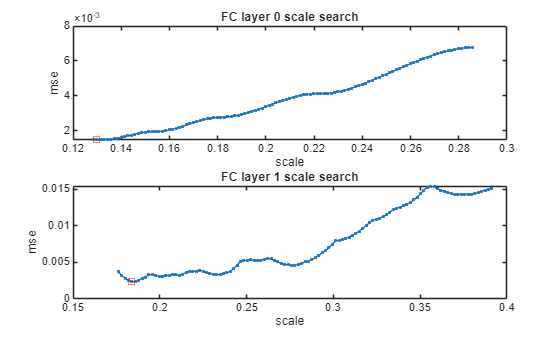

# DIFF at 'layer1-after-Q (i.e. NN output)': max(abs) 118.282318 avg 8.006702 stdev 23.748655 flo/range -174.668747...73.517540


% Generate and calibrate a quantized NN for different weight word lengths,
% keeping other parameters fixed

IO_word_lengths = 4:8;

N = length(IO_word_lengths);

hsims = cell(1,N);
evaluations = cell(1,N);

hwprops.NbitsW = 4;                  % Number of bits used for input and output
hwprops.Nguard = 1;                  % Number of guard bits for accumulator (word length = NbitsIO + NbitsW + Nguard)
hwprops.postQsas = 2;                % When MAC accumulator output is mapped from ACCU word length to the output word length, some multiplication is done to improve precision

for ind = 1:N
    fprintf('Quantized NN for IO word length %d\n',IO_word_lengths(ind));
    hwprops.NbitsIO = IO_word_lengths(ind);  % Number of bits used for I/O
    hsims{ind} = NN_FCRELUFC_SIM(flparams,hwprops);
    hsims{ind}.calibrate(calibration_data,max(abs(calibration_data(:))));  
    evaluations{ind} = hsims{ind}.evaluate(input_data);
end

disp('Floating point outputs mapped against quantized values with varying IO bit widths')

Floating point outputs mapped against quantized values with varying IO bit widths


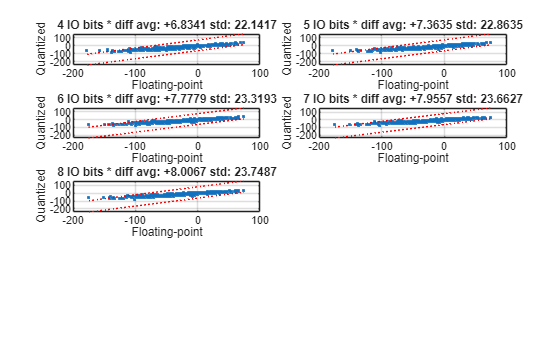


for ind = 1:N
    subplot(4,2,ind);
    v = evaluations{ind};
    mu = mean(v.diff(:));
    stdev = std(v.diff(:));
    plot(v.output_gt,v.output_int,'.');
    hold on
    r = [min(v.output_gt),max(v.output_gt)];
    plot(r,r+mu+3*stdev,'r:');
    plot(r,r+mu-3*stdev,'r:');

    hold off   
    set(gca,'xgrid','on');
    set(gca,'ygrid','on');
    title(sprintf('%d IO bits * diff avg: %+.4f std: %.4f',IO_word_lengths(ind),mu,stdev));

    xlabel('Floating-point');
    ylabel(['Quantized'])
end